# Linear Algebraic Systems

*Supplemental material for Chapter 2 of "Numerical Methods and Chemical Engineering Applications" by Dorfman and Daoutidis.*

*_________________________________________________________________________________________________*

# Learning Objectives

By the end of this module, students will be able to

***Set up a linear system***

- Distinguish a linear system from a nonlinear system.

- Learn to write a linear system in a matrix-vector format.

- Input a linear system into a program.

- Write applicable engineering models in a linear format.

***Characterize linear systems***

- Determine the bandwidth(s) of a linear system.*

- Determine if a linear system has a unique solution.

- Determine if a solution of a linear system is a meaningful result (is it well-posed?).

***Solve a linear system***

- Solve a linear system by Gauss-Elimination.

- Solve a linear system by LU factorization.

- State when numerical errors may occur in Gauss-Elimination and how to resolve them.*

- State some conditions for the convergence of Jacobi and Gauss-Siedel methods.*

*Not covered in tutorial.

## Case Study: Chlorination of Benzene

Monochlorobenzene is a high boiling-point solvent used in many industrial applications ranging from the manufacture of [dyes](https://patentimages.storage.googleapis.com/76/55/12/31756682f755c5/US6013811.pdf), [plastic and rubber processing](https://patentimages.storage.googleapis.com/66/c8/e1/69918f557fbd35/US8563079.pdf), [paints](https://patentimages.storage.googleapis.com/28/17/a7/a40e46f75806cf/US9062206.pdf), and [waxes](https://patents.google.com/patent/US3999960A/en). When benzene and chlorine are mixed, two key reactions occur: **(1)** the chlorination of benzene and

**(2)** the secondary undesirable chlorination of the resulting monochlorobenzene. 

Product purity is ensured by performing a series of separation steps after the initial reaction, and reagant usage is reduced by including a recycle loop. 

**Objective:** A large customer order has been placed for monochlorobenzene that needs to be fulfilled on a tight timeline. The small chemical company you work for has occasionally produced this solvent in the past and has an existing $6{\rm m}^3$continuously stirred tank reactor (CSTR) that will need to be repurposed to produce 25kmol/h monochlorobenzene. Moreover, there isn't sufficient development time available to attempt to improve the processing conditions for the reactor or separators. As a result, you'll need to use the documented process conditions for the reactor and separators which means supplying to the first separator a reactor effluent consisting of 90% benzene, 7% monochlorobenzene, and 3% dichlorobenzene by mole. We need to determine the recycle flow rates and reaction rates required needed to achieve the desired rate at which monochlorobenzene need to be produced. 

Denote benzene as (**A**), monochlorobenzene as (**B**), and dichlorobenzene as (**C**). The mole fraction of species **A** in stream **S1** is denote by $y_{1,A}$ and the molar flowrate **F** [kmol/h] for stream **S1** is denoted $F_1$.

- The feed stream is composed entirely of A and $\rm Cl_2$.

- An excess amount of $\rm Cl_2$ is provided and HCl removal can be assumed to be trivial. So, it's reasonable to exclude it from our design considerations. Moreover, this means the reactions which take place in the reactor vessel can be simplified to **A** → **B** (at rate $r_1$ [kmol/h]) and **B** → **C** (at rate $r_2$ [kmol/h]).

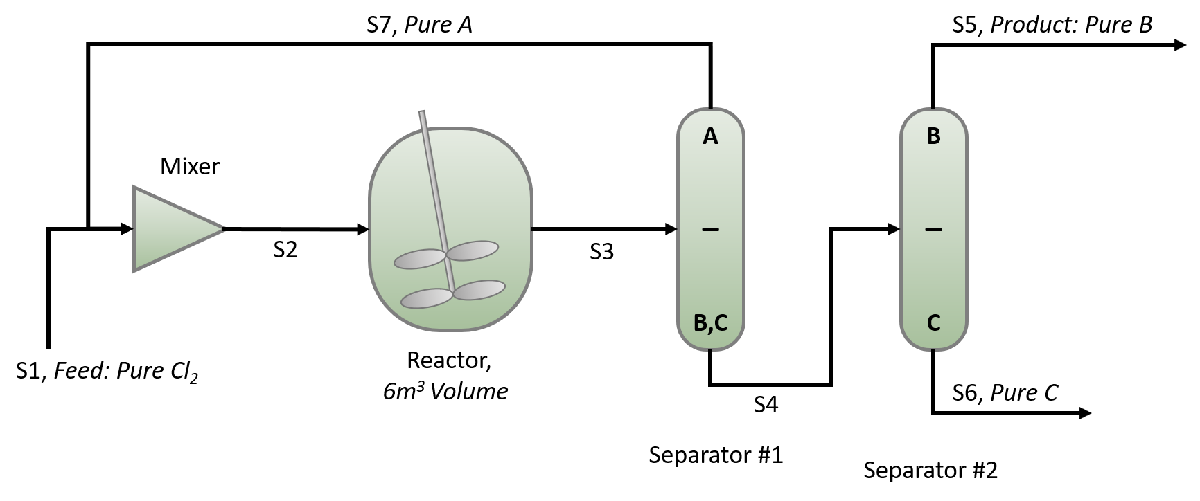

## Variables and Mass Balances

For streams containing only a pure substance, we need only keep track of the total flow rate. Enumerating each quantity in the model is given by $F_1, F_2, F_3, F_4, F_5, F_6, F_7, y_{3,A}, y_{3,B}, y_{3,C}, y_{4,B}, y_{4,C}, r_1, r_2$, and $v$. Five of these are specified (e.g. these are **parameters** with fixed values). This leaves ten degrees of freedom associated with a variable. We'll now need to write out the equations which govern the system (physical laws, equipment specifications, and performance specifications). We'll start with writing the mass balances over each unit operation. 

- Mixer:


$$F_1+F_7-F_2 = 0$$


- Reactor:


$$F_2-r_1v - y_{3,A} F_3 = 0\\
(r_1-r_2)v+y_{3,B} F_3 = 0\\
r_2v - y_{3,C}F_3 = 0$$


- Separator1: 


$$F_3-F_4-F_7=0\\
y_{3,B}F_3-y_{4,B}F_4=0\\
y_{3,C}F_3-y_{4,C}F_4=0$$


- Separator2:


$$F_4-F_6=F_5\\
y_{4,B}F_4=F_5$$


- Relationships


$$y_{4,B}+y_{4,C}=1$$


**Now, take a minute to inspect the model and categorize the system of equations...**       

The 2nd and 3rd equations for Separator 1 as well as the 2nd equation in Separator 2 contain the expressions $y_{4,B}F_4$ and $y_{4,C}F_4$. These terms consist of two variables being multiplied by one another (a **bilinear term**) which is one of simplest commonly encountered nonlinear term. All other expressions consist of addition, subtraction, and the multiplication of a parameter by a variable. So this system of equations is nonlinear but would be linear if we ommitted the expressions: $y_{4,B}F_4$ and $y_{4,C}F_4$. 

**It's often useful to reformulate a model (algebraicly rearrange and potentially introduce new variables) to arrive at a more easily solvable form.** 

We'll start by introducing two new variables: the molar flowrates $F_{4,B}$ and $F_{4,C}$ defined as:


$$F_{4,B}=y_{4,B}F_4\\
F_{4,C}=y_{4,C}F_4$$


Thus, we can obtain the corresponding molar flowrate expression for **S4**: $F_{4,B} + F_{4,C} - F_4=0$. 

Next, we'll introduce the variables: $F_{3,A}$, $F_{3,B}$, and $F_{3,C}$ defined as:

$F_{3,A}$ = $y_{3,A} F_3$

$F_{3,B}$ = $y_{3,B} F_3$

$F_{3,C}$ = $y_{3,C} F_3$

We can then write an additional equation for the molar flowrates of **S3**:

Molar flowrate expressions for** S3**:

$F_{3,A}$ + $F_{3,B}$ + $F_{3,C}$ = $F_3$

We can then rearrange the mass balances for the Reactor, Separator 1, and Separator 2.

- Reactor (Individual Component Mass Balances):


$$F_2-r_1v -  F_{3,A} = 0\\
(r_1-r_2)v+ F_{3,B} = 0\\
r_2v - F_{3,C} = 0$$


- Reformulated Separator 1 Mass Balances:


$$F_3-F_4-F_7=0\\
F_{3,B}-F_{4,B}=0\\
F_{3,C}-F_{4,C}=0$$


- Reformulated Separator 2 Mass Balances:


$$F_4-F_6=F_5\\
F_{4,B}=F_5$$


Then we can derive the modifed system of equations:


$$\begin{array}{l}
F_1 -F_2 +F_7 =0\\
\begin{array}{l}
F_2 -r_1 v-F_{3,A} =0\\
\left(r_1 -r_2 \right)v+F_{3,B} =0\\
r_2 v-F_{3,C} =0
\end{array}\\
\begin{array}{l}
F_3 -F_4 -F_7 =0\\
F_{3,B} -F_{4,B} =0\\
F_{3,C} -F_{4,C} =0
\end{array}\\
\begin{array}{l}
F_4 -F_6 =F_5 \\
F_{4,\mathrm{B}} =F_5 
\end{array}\\
F_{4,B} +F_{4,C} -F_4 =0\\
F_{3,A} +F_{3,B} +F_{3,C} -F_3 =0\\
F_{3,A} -y_{3,A} F_3 =0\\
F_{3,B} -y_{3,B} F_3 =0
\end{array}$$


In order to write these equations in a matrix-vector form: we'll first need to associate each variable (excluding **parameters**) in the model with a component in a vector of variables, $\mathbf x$:


$$\mathbf x = (F_1,F_2,F_3,F_{3,A},F_{3,B}, F_{3,C}, F_3,F_{4,B},F_{4,C}, F_4, F_6,F_7,r_1,r_2)$$


so $x_1=F_1$, $x_2 = F_2$, and so on until we have $x_{13} = r_2$

## Solution:

We consider to use **Gauss elimination** to solve this linear system.

***Interactive! ***Now we enter the above linear equations in matrix-vector form. you should fill the mass balance entries for **separator 1** by yourself:

% Define the Mx = b linear system

% Define storage for linear system
M = zeros(13,13);    % Makes an 2d array of size 13-by-13. This array has 13 rows and 13 columns.
b = zeros(13,1);     % Makes a column vector of size 13. A vector with 13 rows and 1 column.

% Input parameters
y3A = 0.90;      % effluent benzene concentration of reactor
y3B = 0.07;      % effluent monochlorobenzene concentration of reactor
y3C = 0.03;      % effluent dichlorobenzene concentration of reactor
V = 6;           % reactor volume
F_5 = 25.0;      % flow rate of monochlorobenzene required

%%% Mixer Mass Balance %%%
% fills in the first row (which corresponds to the first model equation)
M(1,1) = 1;        % Set the matrix M's entry in the first row and first column to 1
M(1,2) = -1;       % Set the matrix M's entry in the first row and second column to -1
M(1,8) = 1;        % Set the matrix M's entry in the first row and eight column to 1
% b[1] and all other entries of M in row #1, so no need to change these values

%%% Reactor Mass Balance %%%
% reactor - equation #1       
M(2,2) = 1.0;     
M(2,3) = -1.0;
M(2,12) = -V;
% reactor - equation #2     
M(3,4) = 1.0;          
M(3,12) = -V;
M(3,13) = V;
% reactor - equation #3 
M(4,5) = -1.0;        
M(4,13) = V;

%%% Separator 1 Mass Balance %%%

% FILL IN THE REST BELOW HERE IN ROWS 5 to 7 of M!!!!!!!!

%%% Seperator 2 Mass Balance %%%
% equation #1
M(8,9) = 1.0;        
M(8,10) = -1.0;              
b(8) = F_5;

% equation #2
M(9,8) = 1.0;                    
b(9) = F_5;

%%% Molar Flowrate Expressions %%%
% stream 4 balance
M(10,8) = 1.0;  
M(10,9) = -1.0;
M(10,7) = 1.0;
% stream 3 balance #1 
M(11,3) = 1.0;        
M(11,4) = 1.0;
M(11,5) = 1.0;
M(11,6) = -1.0;
% stream 3 balance #2
M(12,3) = 1.0;  
M(12,6) = -y3A;
% stream 4 balance #3
M(13,4) = 1.0;  
M(13,6) = -y3B;

Then we use Gauss elimination to solve this problem, the function `linear_gauss_pivot` is defined in the last section.

x = linear_gauss_pivot(M,b) % Gauss elimination with pivot

## Well-posed problems and the Condition Number 

While a linear system, $\mathbf{M} \mathbf{x} = \mathbf{b}$, may have a unique solution, we also seek to understand whether using a particular algorithm to solve $\mathbf{M} \mathbf{x} = \mathbf{b}$ will yield an accurate solution. We often don't know $\mathbf M$ or $\mathbf b$ exactly. As a consequence, solutions which vary greatly when $\mathbf M$ or $\mathbf b$ are slightly perturbed may be suspect. This is generally assessed by evaluating the **condition number** of a linear system and is defined as: $\textrm{cond}\left(\mathbf{M}\right)=\left|\right|\mathbf{M}\left|\right|\times \left|\right|{\mathbf{M}}^{-1} \left|\right|$. A derivation of this is given in section 2.3.4 of Dorfman and  Daoutidis, Numerical Methods with Chemical Engineering Applications  which arrives at the following inequality:


$$\Delta \mathbf{x}\le \textrm{cond}\left(\mathbf{M}\right)\left(\frac{\left\|\Delta \mathbf{b}\right\|\left\|\mathbf{x}\right\|}{\left\|\mathbf{b}\right\|}\right)$$


For a fixed condition number, $\textrm{cond}\left(\mathbf{M}\right)$, solution $\mathbf{x}$, and $\mathbf{b}$ if we slightly perturb $\mathbf{b}$ by $\Delta \mathbf{b}$ then $\mathbf{x}$ may change by at most an amount proportional to the condition number.  Another way of interpreting this is by applying the following rule of  thumb: the condition number $\kappa$ means that the method looses $\log_{10} \left(\kappa \right)$ of accuracy relative to rounding error.

If an application leads to an ill-posed problem (values of $\mathbf M$ and $\mathbf b$ may be known to very high precision), there are a multitude of ways  this may be dealt with. This most common and often most robust approach  is to apply a [**preconditioner**](http://www.mathcs.emory.edu/~benzi/Web_papers/survey.pdf). That is we find an appropriate matrix $\mathbf Y$ and multiply both sides of the original linear system to create an equivalent new linear system, $(\mathbf Y \mathbf M) \mathbf x = (\mathbf Y \mathbf b)$, which has a lower condition number. We can then solve the equivalent modified system. 

cond_M = cond(M)

We can also easily solve this problem using the **LU decomposition** method (with pivoting) using MATLAB embeded `lu` function ( You should complete the matrix M in the interactive code)

[L,U,P] = lu(M); % LU matrix factorization
y = L\(P*b);
x = U\y

# Questions for reflection

- What varieties of problems may result in a banded matrix?

- What does it mean that an iterative method converged? 

- When is an absolute or relative convergence criteria preferable?

- When is solving by one method versus another preferable (e.g. Banded Gauss-Elimination versus Gauss-Siedel)?

The Gausss elimination w/ partial pivoting algorithm used in the Case Study is defined as:

function x = linear_gauss_pivot(A,b)
% Inputs:
% A = n x n matrix
% b = column vector, n x 1
% Output:
% x = column vector, n x 1
n = length(b);
x = zeros(n,1);
% forward elimination
for k = 1:n-1
    % check for best pivot
    Amax = A(k,k);
    swap_row = k;
    for i = k+1:n
        if abs(A(i,k)) > abs(Amax)
            Amax = A(i,k);
            swap_row = i;
        end
    end
    % swap rows when previous if statement is true
    if swap_row ~= k
        old_pivot = A(k,:);
        old_b = b(k);
        A(k,:) = A(swap_row,:);
        A(swap_row,:) = old_pivot;
        b(k) = b(swap_row);
        b(swap_row) = old_b;
    end
    % elimination
    for i = k+1:n
        m = A(i,k)/A(k,k);
        for j = k+1:n
            A(i,j) = A(i,j) - m*A(k,j);
        end
        b(i) = b(i) - m*b(k);
    end
end
% back substitution
x(n) = b(n)/A(n,n);
for i = n-1:-1:1
    S = b(i);
    for j = i+1:n
        S = S - A(i,j)*x(j);
    end
    x(i) = S/A(i,i);
end
end